# Ayudantía N°2

**Magíster Economía PUC**

**Teoría Macroeconomómica I**

Estudiante: Valentina Andrade de la Horra Profesor: Alexandre Janiak

## 1.Operaciones con variables aleatorias

Modificamos la matrix xx.m de la ayudantía pasada y creamos una matriz_2.m que contiene como *inputs* el tamaño del vector (fi�la y columna) y un parámetro i = {1,2,3,4} que determina cuál de las siguientes distribuciones será la generadora de dichos números, donde los *outputs* son

- 
$$X_{1\;} =X\sim U\;\left(1,4\right)$$


- 
$$X_{1\;} =X\sim X{\;}_3^2$$


- 
$$X_{1\;} =X\sim \exp \left(1\ldotp 1\right)$$


- 
$$X_{1\;} =X\sim t-\textrm{student}\;2\;\textrm{gl}\;$$


1.La cantidad de números aleatorios que necesita para llegar a sumar 20.

Debemos construir una funcion que me devuelva "vector" (r,c) para que para cada modelo me indique cuantas veces se debe sumar para sumar 20. Partimos de valores auxiliares

[vector, modelos] = matriz_2(100,1,2)

Modelo 2


vector =     3.2063
    1.0935
    0.1863
    0.5849
    0.0022
    1.6521
    0.0218
    4.9468
    0.3439
   15.9694


modelos =    1.9374 + 0.0000i   3.2063 + 0.0000i  -0.6454 + 0.0000i  -1.0000 + 0.0000i
   3.0817 + 0.0000i   1.0935 + 0.0000i   0.8415 + 0.0000i   1.0000 + 0.0000i
   3.6721 + 0.0000i   0.1863 + 0.0000i   0.2605 + 0.0000i   1.0000 + 0.0000i
   2.4720 + 0.0000i   0.5849 + 0.0000i   0.5296 + 0.0000i   1.0000 + 0.0000i
   3.4175 + 0.0000i   0.0022 + 0.0000i  -0.0242 + 0.0000i  -1.0000 + 0.0000i
   1.9793 + 0.0000i   1.6521 + 0.0000i  -0.5046 + 0.0000i  -1.0000 + 0.0000i
   2.6496 + 0.0000i   0.0218 + 0.0000i  -0.0744 + 0.0000i  -1.0000 + 0.0000i
   2.1664 + 0.0000i   4.9468 + 0.0000i  -0.7509 + 0.0000i  -1.0000 + 0.0000i
   3.6905 + 0.0000i   0.3439 + 0.0000i  -0.2651 + 0.0000i  -1.0000 + 0.0000i
   3.0284 + 0.0000i  15.9694 + 0.0000i  -0.2435 - 2.8560i   1.0000 + 0.0000i


A=1:4;

**Explicación: **La programación dice que para todo modelo A = [1:4] se alcanza la suma == 20 a partir de la cantidad de filas (cantidad (i)) que corresponde al vector j (dinámico). Entonces se van sumando j+1 elementos hasta alcanzar 20 para cada modelo que se estima (en i y j =1 agarra el primer elemento de la primera columna)

for i=1:length(A)% Para todo modelo (variable aleatoria)
        suma=0;
        j=0;
        while suma==20 % hasta 20
           j=j+1; % En j + elemento (dinámico)
           suma=suma+modelos(j,i);  %suma 0 + modelos(j,i)
           cantidad(i)=j; %sumas(i)=suma
        if j>1000 
                break;
        end            
            end
        disp(['Usando el modelo ',num2str(A(i)),' se requiere sumar ',num2str(cantidad(i)),' veces para alcanzar 20.'])
end

Usando el modelo 1 se requiere sumar 9 veces para alcanzar 20.
Usando el modelo 2 se requiere sumar 7 veces para alcanzar 20.
Usando el modelo 3 se requiere sumar 75 veces para alcanzar 20.
Usando el modelo 4 se requiere sumar 100 veces para alcanzar 20.


2. La cantidad de números aleatorios que necesita para alcanzar un número mayor que uno.

for i=1:length(A)
       j=1;
        while modelos(j,i)<1
            elemento=modelos(j,i);
            columna=find(modelos(:,i)==elemento);
            j=j+1; 
        end
        disp(['Usando el modelo ',num2str(A(i)),' se requiere tomar ',num2str(j),' veces para alcanzar un valor mayor que uno.'])
end

Usando el modelo 1 se requiere tomar 1 veces para alcanzar un valor mayor que uno.
Usando el modelo 2 se requiere tomar 1 veces para alcanzar un valor mayor que uno.
Usando el modelo 3 se requiere tomar 12 veces para alcanzar un valor mayor que uno.
Usando el modelo 4 se requiere tomar 2 veces para alcanzar un valor mayor que uno.


3.La cantidad de números aleatorios que necesita para que la media del vector aleatorio sea al menor que 0.7

for i=1:length(A)
       j=1;
       media=0;
        while media < 0.7 % Hasta media menor 0.7
           media=mean(modelos(1:j,i));
           j=j+1;
            if j>100
                break;
            end
        end
       disp(['Usando el modelo ', num2str(A(i)),' requerimos tomar ',num2str(j),' numeros para la media requerida'])
end

Usando el modelo 1 requerimos tomar 2 numeros para la media requerida
Usando el modelo 2 requerimos tomar 2 numeros para la media requerida
Usando el modelo 3 requerimos tomar 101 numeros para la media requerida
Usando el modelo 4 requerimos tomar 101 numeros para la media requerida


## 2.Solución sistemas no lineales

(a) Ingresamos el vector $\left\lbrack a_{1\;} ,a_2 \;,b_{1\;} ,b_2 ,s_1 ,s_2 \right\rbrack =\left\lbrack 2,1,1,2,1,1\right\rbrack$ y un par de valores iniciales en un vector$\;{\textrm{Ini}}_{1\textrm{x2}}$. Reescribimos la función que se presenta acontinuación como $f\left(x\right)=0\;$para los parámetros solicitados


$$\begin{array}{l}
a_1 x-a_2 y=e^{{\;}^{-s_1 x} } \\
b_1 x-b_2 y=e^{{\;}^{-s_1 y} } 
\end{array}$$


Resolvemos


$$\begin{array}{l}
\\
f\left(x\right)=\left\lbrace \begin{array}{ll}
a_1 x-a_2 y-e^{{\;}^{-s_1 x} } =0 & \left(1\right)\\
b_1 x-b_2 y-e^{{\;}^{-s_1 y} } =0 & \left(2\right)
\end{array}\right.
\end{array}$$


x_i = [2 1 1 2 1 1] % [a1 a2 b1 b2 s1 s2]

x_i =      2     1     1     2     1     1


ini=[5,5];

% Parametros (indexacion)
a1=x_i(1,1);
a2=x_i(1,2);
b1=x_i(1,3);
b2=x_i(1,4);
s1=x_i(1,5);
s2=x_i(1,6);

xa=linspace(-10,20,1000);
ya=linspace(-10,20,1000); 
[x,y]=meshgrid(xa,ya);

%Funciones
f1=a1*x - a2*y -exp(-s1*x); 
f2=-b1*x + b2*y -exp(-s2*y);


(b) Gráfico

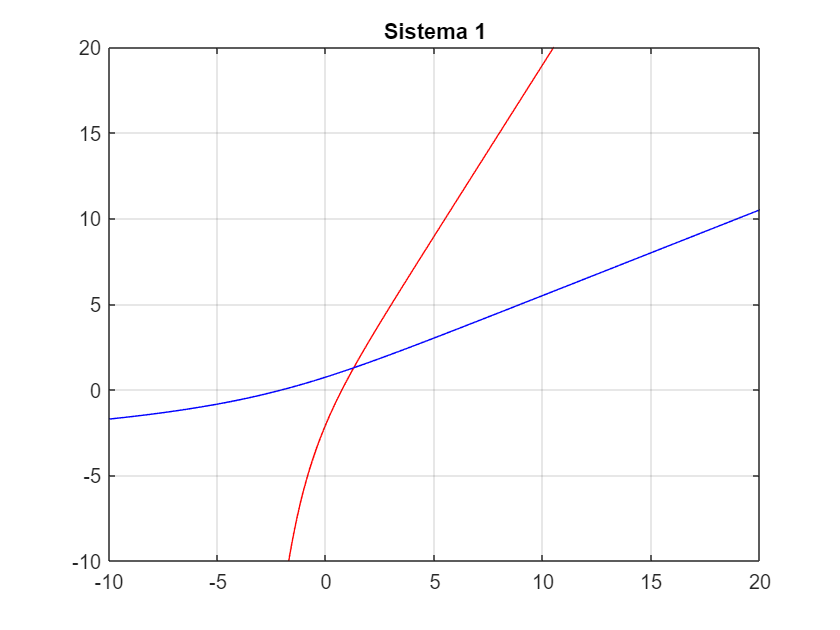

figure(1)
contour(x,y,f1,[1,1],'red'); 
hold on; 
grid on; 
contour(x,y,f2,[1,1],'blue');
set(gcf,'color','w'); 
title('Sistema 1')
hold off;

(c) Resolvemos el sistema de ecuaciones y mostraremos** iterativamente** cómo llega al resultado mediante programación de ciclos (método de iteración). Indicaremos cuantas iteraciones nos toma resolver el sistema

tol=0.0003;
x0=ini(1);
y0=ini(2);
x1=10;
y1=10;
diff=10;
i=0;    
while diff>tol
i=i+1;
x1=x0-(a1*x0 - b1*y0 -exp(-s1*x0)); 
y1=y0-(-a2*x0 + b2*y0 -exp(-s2*y0));
diff=abs(max((x1-x0),(y1-y0)));
XX(i,1)=x1;
YY(i,1)=y1;
x0=x1;
y0=y1;
end

F=['Solucion: ',num2str(x0),' ',num2str(y0), 'Iteraciones', i ] 

F = 'Solucion: 0.56707 0.56707Iteraciones'

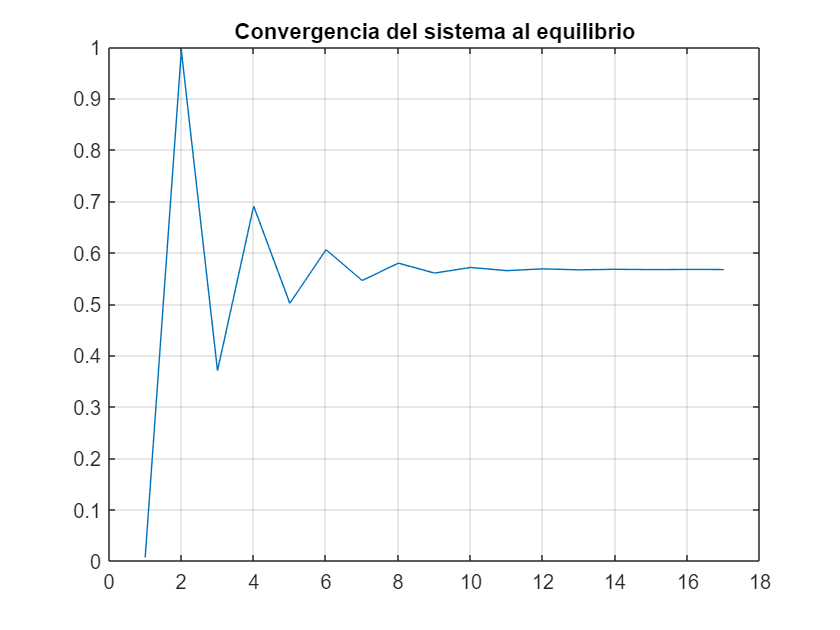

figure(2)
plot(XX);
grid on;
title('Convergencia del sistema al equilibrio')

set(gcf,'color','w');

(d) Repetimos (b) empleando las opciones de la función *fsolve*

x0 = [5;5]; options = optimoptions('fsolve','Display','iter');
[x,fval] = fsolve(@myfunction,x0,options)


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3         146.081                          16.9               1
     1          6          109.73              1           13.6               1
     2          9         43.8189            2.5           8.04             2.5
     3         12         3.81035        4.35451           3.62            6.25
     4         13         3.81035        10.8863           3.62            10.9
     5         14         3.81035        2.72157           3.62            2.72
     6         17         3.20678       0.680393           1.42            0.68
     7         20         3.08172       0.680393           1.49            0.68
     8         21         3.08172       0.680393           1.49            0.68
     9         24         2.65449       0.170098          0.467            0.17
    10         27         2.64828       0.1

x =     0.1040
   -0.6931


fval =    -0.0000
   -1.6137


(e) Empleamos las funciones *fzero* y *fsolve* para resolver $f\left(x\right)=\;x^5 -5x^{2\;} +8x-5x{\;}^{\frac{1}{2}} =2$

**fzero** es una función que nos dice las raices de la función no lineal, es decir donde la función cruza el eje x. 

fun = @(x) x.^5 -5*x + 8*x -5*x.^0.5 - 2;
xo = 2; % punto inicial

Error using fzero (line 184)
FUN must be a function, a valid character vector expression, or an inline function object.

z = fzero(@f, xo)

También cree la función @f (en f.m) pero para algo tan pequeño siento que se "pierde" más de lo que se gana

Como $f\left(x\right)$ es un polinomio, podemos encontrar el mismo cero de la función y un par de ceros complejos usando el comando *roots*

roots([1 -5 8 -5 -2])

También los podemos graficar

options = optimset('PlotFcns',{@optimplotx,@optimplotfval});
z = fzero(@f, xo, options)

**fsolve** es una función que permite conocer las raices de una solución a partir de la iteración de variables 

options = optimoptions('fsolve','Display','iter');
[x,fval] = fsolve(@f2,x0,options)

Como podemos notar **fsolve** tiene dos soluciones, mientras que **fzero** tiene solo una. Esto es básicamente pues las raices de la solución en **fsolve** pueden estar cerca del cero pero no ser cero. Entonces, podemos notar que **fsolve** es un algoritmo que soluciona un sistema de ecuaciones o una ecuaciín con un grado de tolerancia, y que se basa su modo de estimación en una iteración de parámetros mientras que **fzero** no. 

## 3.Aproximación del numero *e*

En este caso se pide estimar mediante el procedimiento de simulación de Montecarlo basado en* Estimating the Value of e by Simulation, Russell el número e *(*número de Euler*). La idea general es que $E\;\left(Z\right)=e$ donde *Z* es una variable aleatoria que se de�ne de la siguiente manera:


$$Z=\min \;\lbrace n\;|\;$$

$$\sum_{i=1} X_i >1\rbrace ,X_i \sim U\;\left(0,1\right)$$


es decir, *Z *representa el mínimo de *n *que alcanza cuando la suma de las variables aleatorias es mayor que 1.

Generaremos un programa que aproxime el numero *e *según lo planteado, es decir, comprararemos lo obtenido en una simulacuón con respecto al número *e *(en términos reltivos) donde debe utilizar una tolerancia de $10{\;}^{-6} \ldotp$

## 4. Optimización y simulación Montecarlo

Suponga una función de producción


$$F\left(L,K\right)=A*L^{0\ldotp 4\;} K^{0\ldotp 4} \;$$


Donde *A* es un parámetro fijo, *L* es la cantidad de horas trabajadas en cada puesto y *K *es un indicador del nivel de capital de la firma

(a) Graficaremos las **isocuantas** de esta función de producción, con A = 100. Para hacerlo considere la función G(L,K). Emplearemos vectores con valores equidistantes de intervalo [0,10] en $R^{100}$ para cada variable K y L. Cada puesto de trabajo paga *w = 50.000* por hora trabajada normal (hasta 160 horas por periodo), y paga *w*1.5* por hora extra. Supondremos que la tasa de interés es *r = 0.05*

(b) Compute una función de costos C(X), donde X es un vector conformado por valores de (L,K), y una función de producción $f\left(A,X\right)\ldotp$

(c) Solución el problema de la empresa para estos parámetros, con z = 1. Usaremos *fminsearch *la función de beneficios definida como función handle. Calcularemos los beneficios en el óptimo

(d) Supondremos que z es una variable aleatoria con distribución $\frac{\exp \left(5\right)}{100+1}$ (graficado en histogramas) y estimamos empleado el método de montecarlo con 1000 simulaciones los beneficios promedios, el percentil 90 y el 10 esperados. 

(e) ¿Cuál es el mínimo valor que tendrá el conjunto del 20% de mayores beneficios?

## Seguimiento II: MATLAB

Para el siguiente sistema de ecuaciones en (x,y,z):


$$\begin{array}{l}
f\left(x\right)=\left\lbrace \begin{array}{ll}
a_1 x+b_1 \textrm{ry}+c_1 \textrm{rz}=s_1  & \left(1\right)\\
a_2 x+b_{2\;} y+c_2 \left(2r-1\right)z=s_2  & \left(2\right)
\end{array}\right.\\
{\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;a}_3 x+b_3 \left(r-1\right)y+c_3 \textrm{rz}=s_3 \;\;\;\;\;\;\left(3\right)
\end{array}$$


(a) Ingresar las matrices $A_{3\textrm{x3}}$ de coeficientes $r_{1\textrm{x4}}$ de parámetros y $s_{1\textrm{x3}}$ de soluciones

(b) Dados los valores de $A$ y $S$, elaboramos un programa que determina el sistema de ecuaciones (1) tiene aolución para cada valor de $r\ldotp$

(c) Armar una interfaz que comuniqué al usuario qué tipo de sistemas está analizando: indeterminado, determinado, para cada valor de $r,\;$y la matriz A resultados.

(d) Resolver el sistema para r

(e) Agregamos el comando que evalúa si (d) es correcto empleando el co,ando linsolve e informamos al usuario el resultado o que hay errores


$$\textrm{Donde}\;A\;=\left\lbrack \begin{array}{ccc}
1 & -4 & 6\\
-4 & 5 & 18\\
1 & 2 & 2
\end{array}\right\rbrack ,S=\left\lbrack \begin{array}{ccc}
1 & 2 & 3
\end{array}\right\rbrack \;y\;r=\left\lbrack \begin{array}{cccc}
1 & 2 & 3 & 4
\end{array}\right\rbrack$$
